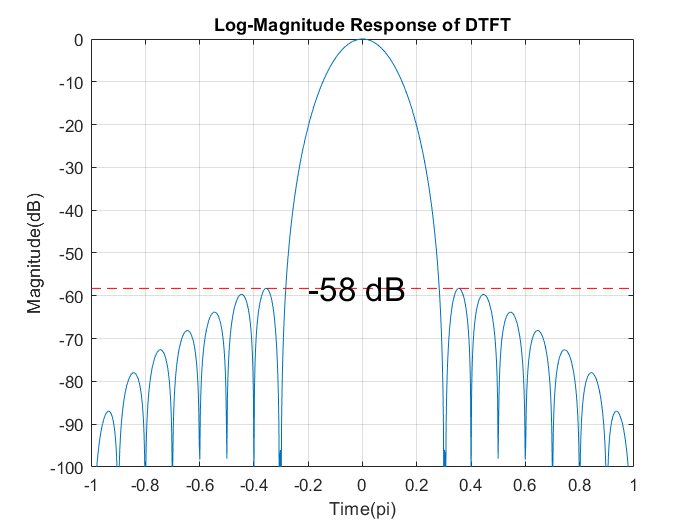

om = linspace(-pi, pi, 1024);
om_len = length(om);
L = 21;
blackm = blackman(L);

blackm_dtft = freqz(blackm, 1, om);

blackm_dtft = blackm_dtft./max(abs(blackm_dtft));

[pks,locs] = findpeaks(20*log10(abs(blackm_dtft)),om);
pks_sort = sort(pks,"descend");
sidelobe = pks_sort(2); 
text_8a = [int2str(sidelobe), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_dtft))); grid on;
title('Log-Magnitude Response of DTFT'); ylim([-100 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe,sidelobe],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe,text_8a, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Magnitude Response)", sidelobe);

Peak of the first sidelobes is -58.256904 dB (in Magnitude Response)

close all; clear;
fprintf('8(b): L = 21\n');

8(b): L = 21



om = linspace(-pi, pi, 1024);
om_len = length(om);
L = 21; M = L - 1;
blackm = blackman(L);
blackm_dtft = freqz(blackm, 1, om);
blackm_dtft = blackm_dtft./max(abs(blackm_dtft));
[pks,locs] = findpeaks(20*log10(abs(blackm_dtft)),om);
pks_sort = sort(pks,"descend");
sidelobe = pks_sort(2); 
text_8a = [int2str(sidelobe), ' dB'];

% Use Type I linear phase filter find amplitude response
blackm_amp = blackm((length(blackm)+1)/2);
j = 1;
for i = ((length(blackm)-1)/2):-1:1
    blackm_amp = blackm_amp + (2*blackm(i)*cos(om.*j));
    j = j + 1;
end

blackm_cum = cumsum(blackm_amp);
blackm_cum = blackm_cum ./ max(blackm_cum);

[pks,locs] = findpeaks(20*log10(abs(blackm_cum)),om);
sort_cum = sort(pks,"descend")

sort_cum =          0   -0.0009   -0.0013   -0.0025  -75.4574  -78.4495  -79.4546  -83.7484  -88.0916  -92.9082  -99.6935


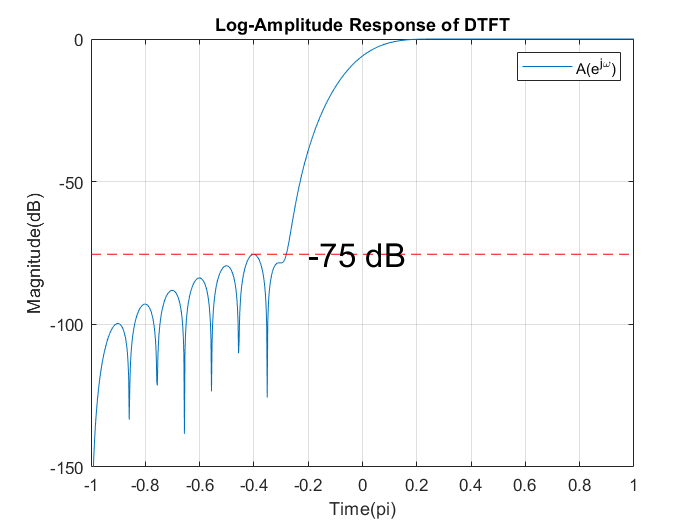

sidelobe_cum = sort_cum(5); 
text_8b = [int2str(sidelobe_cum), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_cum))); grid on;
title('Log-Amplitude Response of DTFT'); ylim([-150 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe_cum,sidelobe_cum],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe_cum,text_8b, 'Fontsize', 20);
legend('A(e^j^\omega)')
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Magnitude Response)", sidelobe);

Peak of the first sidelobes is -58.256904 dB (in Magnitude Response)

fprintf("Peak of the first sidelobes is %f dB (in Amplitude Response)\n", sidelobe_cum);

Peak of the first sidelobes is -75.457425 dB (in Amplitude Response)


close all; clear;
om = linspace(-pi, pi, 1024);
om_len = length(om);

L = 41;
blackm = blackman(L);
blackm_dtft = freqz(blackm, 1, om);
blackm_dtft = blackm_dtft./max(abs(blackm_dtft)); % nomorlize

% Use Type I linear phase filter find amplitude response
blackm_amp = blackm((length(blackm)+1)/2);
j = 1;
for i = ((length(blackm)-1)/2):-1:1
    blackm_amp = blackm_amp + (2*blackm(i)*cos(om.*j));
    j = j + 1;
end

% Find the accumulated amplitude response
blackm_cum = cumsum(blackm_amp);
blackm_cum = blackm_cum ./ max(blackm_cum); % nomorlize

[pks,locs] = findpeaks(20*log10(abs(blackm_dtft)),om);
sort_dtft = sort(pks,"descend");
sidelobe = sort_dtft(2); 
text_dtft = [int2str(sidelobe), ' dB'];

[pks,locs] = findpeaks(20*log10(abs(blackm_cum)),om);
sort_cum = sort(pks,"descend")

sort_cum =          0   -0.0009   -0.0012   -0.0013   -0.0014   -0.0014   -0.0015   -0.0015   -0.0025  -75.2990  -78.2927  -79.1173  -83.0529  -86.6333  -89.8956  -92.8467  -95.5739  -98.1214 -100.5318 -102.8890 -105.2055 -107.6154 -110.2008 -113.2002 -117.0791 -123.3018


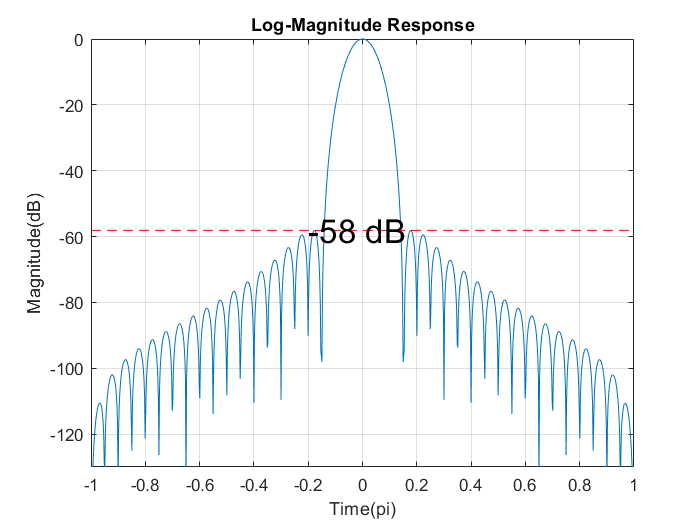

sidelobe_cum = sort_cum(10); 
text_cum = [int2str(sidelobe_cum), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_dtft))); grid on;
title('Log-Magnitude Response'); ylim([-130 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe,sidelobe],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe,text_dtft, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');

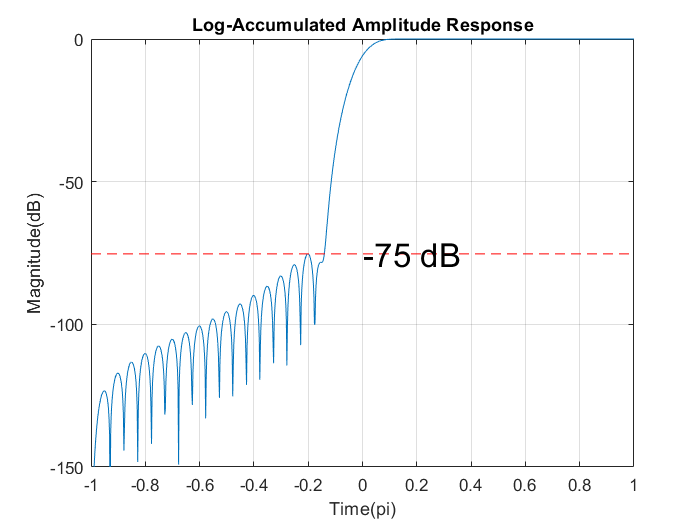


figure; plot(om/pi, 20*log10(abs(blackm_cum))); grid on;
title('Log-Accumulated Amplitude Response'); ylim([-150 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe_cum,sidelobe_cum],'linestyle','--', 'color', 'r');
text(0,sidelobe_cum,text_cum, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Magnitude Response)\n", sidelobe);

Peak of the first sidelobes is -58.119680 dB (in Magnitude Response)


fprintf("Peak of the first sidelobes is %f dB (in Amplitude Response)\n", sidelobe_cum);

Peak of the first sidelobes is -75.299049 dB (in Amplitude Response)
